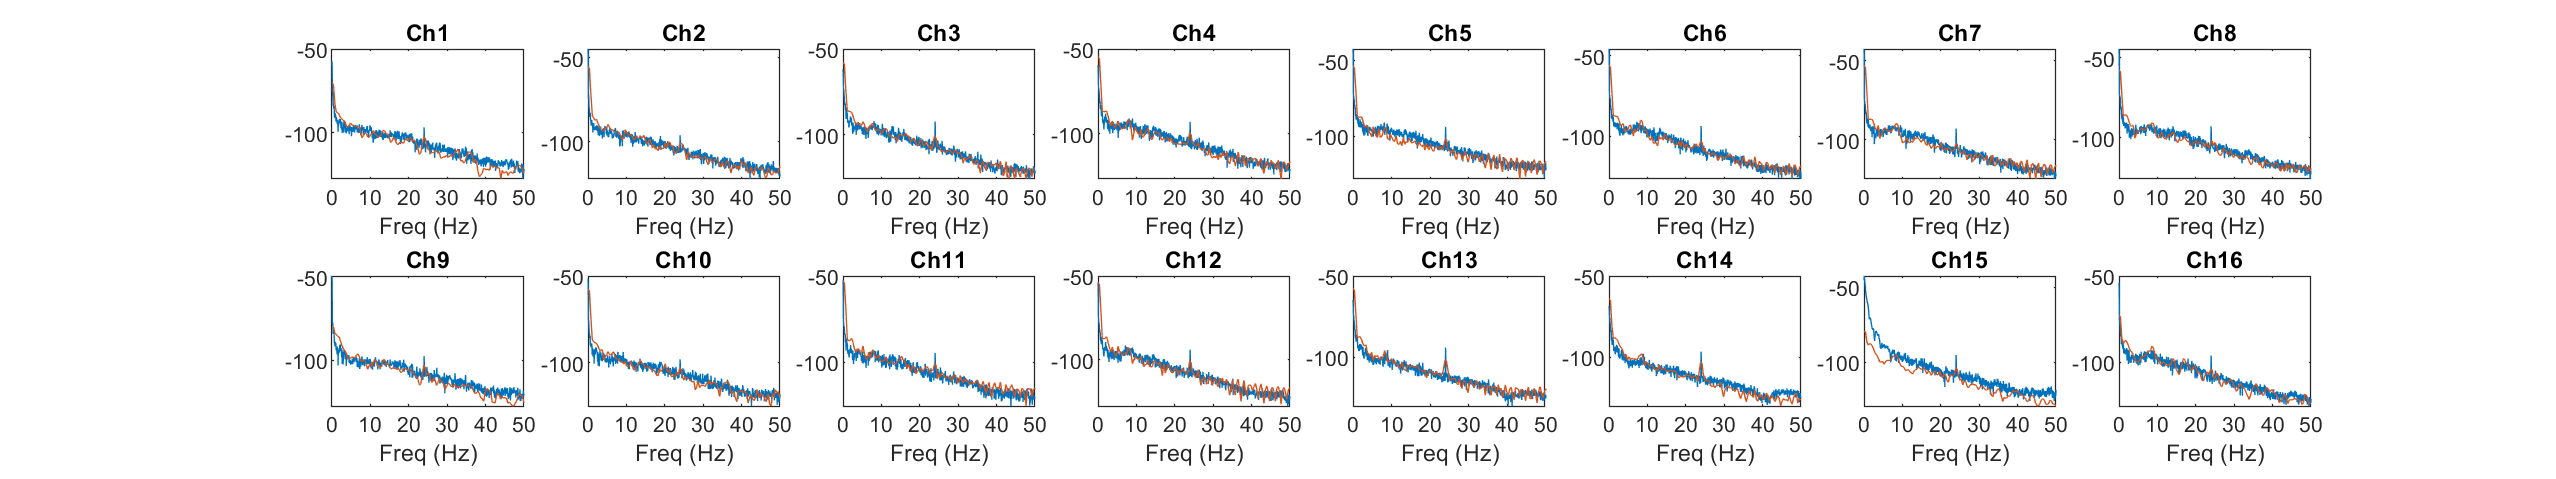

clear
% flags
saveplot = false;%true;
use_artrem = false;%true;

subjects = ["0d6df", "05a8c", "48bba", "92a04", "7916b", "72542", "b60e1"];
artrems = [false, false, false, true, true, false, false];
for i=7%:length(subjects)
    subject = subjects(i);
    if subject == "48bba"
        data_pre = "iTBS-3_split_1.mat";
        data_post = "iTBS-3_split_3.mat";
    else
        data_pre = "iTBS-1_split_1.mat";
        data_post = "iTBS-1_split_3.mat";
    end
    if artrems(i)
        data_pre_proc = "iTBS_"+subject+"_pre.mat";
        data_post_proc = "iTBS_"+subject+"_post.mat";
    end

    cd("C:\Users\Katherine\Documents\AAA UW\Herron Lab\Data\" + subject)
    if use_artrem
        pre = load(data_pre_proc);
        post = load(data_post_proc);
        N_chan = size(pre.data_artrem,2);
    else
        pre = load(data_pre);
        post = load(data_post);
        N_chan = size(pre.data,2);
    end
    
    delay = ceil(post.fs*5); % post resting state begins 5s after final stim onset for method 1
    f = figure();%'Visible','off');
    f.Position(3)=f.Position(3)*2;
    if N_chan > 8
        f.Position(3)=f.Position(3)*2;
    end
    
    for C_r=1:N_chan
        if use_artrem
            x = pre.data_artrem(1:pre.onsets_samps(1),C_r)';
            %y = post.data_artrem(post.onsets_samps(end)+delay:end,C_r)'; % method 1
            y = post.data_artrem(1:post.onsets_samps(1),C_r)'; % method 2
        else
            x = pre.data(1:pre.onsets_samps(1),C_r)';
            %y = post.data(post.onsets_samps(end)+delay:end,C_r)'; % method 1
            y = post.data(1:post.onsets_samps(1),C_r)'; % method 2
        end
        [pxx,fx] = pwelch(x,[],[],[],pre.fs);
        [pyy,fy] = pwelch(y,[],[],[],post.fs);
        
        % plot pre vs post PSD
        subplot(2,N_chan/2,C_r)
        plot(fx,10*log10(pxx))
        hold on
        plot(fy,10*log10(pyy)) %patchline(fy,10*log10(pyy),'edgealpha',0.5)
        xlim([0,50]); xticks(0:10:50); xlabel('Freq (Hz)')
        title("Ch" + num2str(C_r))
    end
    
    if saveplot && use_artrem
        saveas(gcf,"rest_psd_artrem",'png')
    elseif saveplot
        saveas(gcf,"rest_psd2",'png')
    end
end

% FFT
% x = data_artrem(1:onsets_samps(1),3)';
% y = fft(x);
% f = (0:length(y)-1)*fs/length(y);
% plot(f,abs(y)); xlim([0, 125]); ylim([0,100]); xlabel('Frequency (Hz)'); ylabel('Magnitude');

% PSD
% [pxx,f] = pwelch(x,[],[],[],fs);
% plot(f,10*log10(pxx)); xlabel('Frequency (Hz)'); ylabel('PSD');